clear; close all

load MotorX_WO_PID.mat
t_X_WO = out.tout;
input_X_WO = out.simout;
error_X_WO = out.simout1;
CE_X_WO = out.simout2;
offset = -0.5;
output_X_WO = out.simout3-offset;

GX = 1.72;

GX = 1.7200

CE_X_WO= (11.4/255)*GX*CE_X_WO;


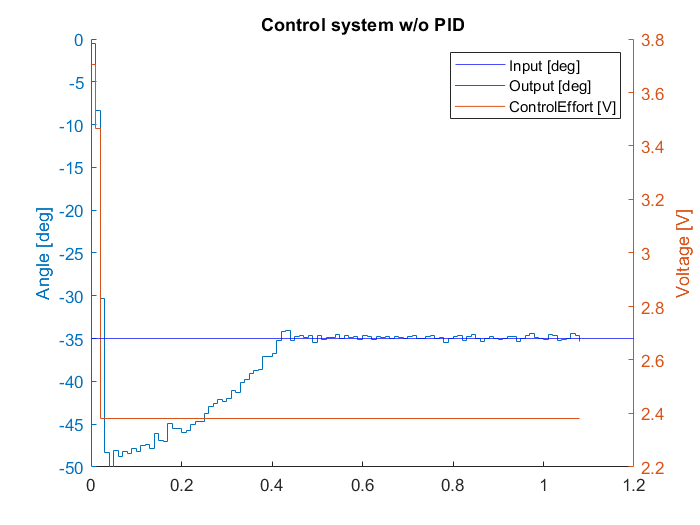

clf;
hold on
yyaxis left
yline(-35,'b')
plot(output_X_WO)
ylabel('Angle [deg]')
ylim([-50 0])


yyaxis right
plot(CE_X_WO)
ylabel('Voltage [V]')


title('Control system w/o PID')
legend('Input [deg]','Output [deg]','ControlEffort [V]')

hold off